sampleRate = 20e6;
oversampling = 1.5;
masterClockRate = sampleRate*oversampling;
platform = 'B200';
serialNum = '310A880';
centerFrequency = 2.412e9;
cm = 1; %selected TX
sdrTransmitter = comm.SDRuTransmitter('Platform', platform, 'SerialNum', serialNum, ...
  'CenterFrequency', centerFrequency, ...
  'MasterClockRate', masterClockRate, ...
  'InterpolationFactor', 1, ...
  'Gain', 40, ...
  'ChannelMapping', cm, ...
  'UnderrunOutputPort',  true);

qos_data = load('qos_data.mat');
p1=qos_data.p1

p1 = 151×2 char array
    '88'
    '02'
    '2c'
    '00'
    '1c'
    '36'
    'bb'
    '1a'
    '43'
    '54'
    '10'
    '0d'
    '7f'
    '6d'
    '9c'
    'fd'
    '10'
    '0d'
    '7f'
    '6d'
    '9c'
    'fd'
    'e0'
    '53'
    '00'
    '00'
    'aa'
    'aa'
    '03'
    '00'
    '00'
    '00'
    '08'
    '00'
    '45'
    '00'
    '00'
    '71'
    'ef'
    'cf'
    '40'
    '00'
    '40'
    '11'
    'c6'
    'a2'
    'c0'
    'a8'
    '01'
    '01'
    'c0'
    'a8'
    '01'
    'b8'
    '00'
    '35'
    '91'
    '06'
    '00'
    '5d'
    '4e'
    '70'
    '4b'
    '19'
    '81'
    '80'
    '00'
    '01'
    '00'
    '01'
    '00'
    '00'
    '00'
    '00'
    '13'
    '69'
    '70'
    '76'
    '36'
    '2d'
    '63'
    '30'
    '31'
    '34'
    '2d'
    '62'
    '72'
    '75'
    '30'
    '30'
    '31'
    '2d'
    '69'
    '78'
    '01'
    '31'
    '03'
    '6f'
    '63'
    '61'
    '09'
    '6e'
    '66'
    '6c'
    '78'
    '76'
    '69'
    '64'
    '6

%t2 = load('netflix_n.mat');
%p1 = t2.packets{1};

psdu_d = reshape(de2bi(hex2dec(p1), 8)', [], 1);
%psdu_d = double(psdu_t)
% Initialize the scrambler with a random integer for each packet
helperWLANExportToPCAP({p1}, 'macFrames_p1.pcap');

HTconfig = wlanHTConfig;
%HTconfig.GuardInterval="Short";
HTconfig.MCS=0;
%HTconfig.ChannelCoding="LDPC";
HTconfig.PSDULength = length(p1);   % Set the PSDU length
HTconfig.AggregatedMPDU=0;

% Initialize the scrambler with a random integer for each packet
scramblerInitialization = randi([1 127],1,1);

% Generate baseband NonHT packets separated by idle time
txWaveform_t = wlanWaveformGenerator(psdu_d,HTconfig, ...
    'NumPackets',1,'IdleTime',0, ...
    'ScramblerInitialization',scramblerInitialization, ...
    "WindowTransitionTime", 0);

% Resample transmit waveform
txWaveform_t  = resample(txWaveform_t,sampleRate*oversampling,sampleRate);

fprintf('\nGenerating WLAN transmit waveform:\n')


Generating WLAN transmit waveform:


% Scale the normalized signal to avoid saturation of RF stages
powerScaleFactor = 0.9;
txWaveform_t = txWaveform_t.*(1/max(abs(txWaveform_t))*powerScaleFactor);
% Cast the transmit signal to int16, this is the native format for the SDR
% hardware
txWaveform_t_int = int16(txWaveform_t*2^15);

sdrTransmitter(txWaveform_t_int)

ans = uint32
0

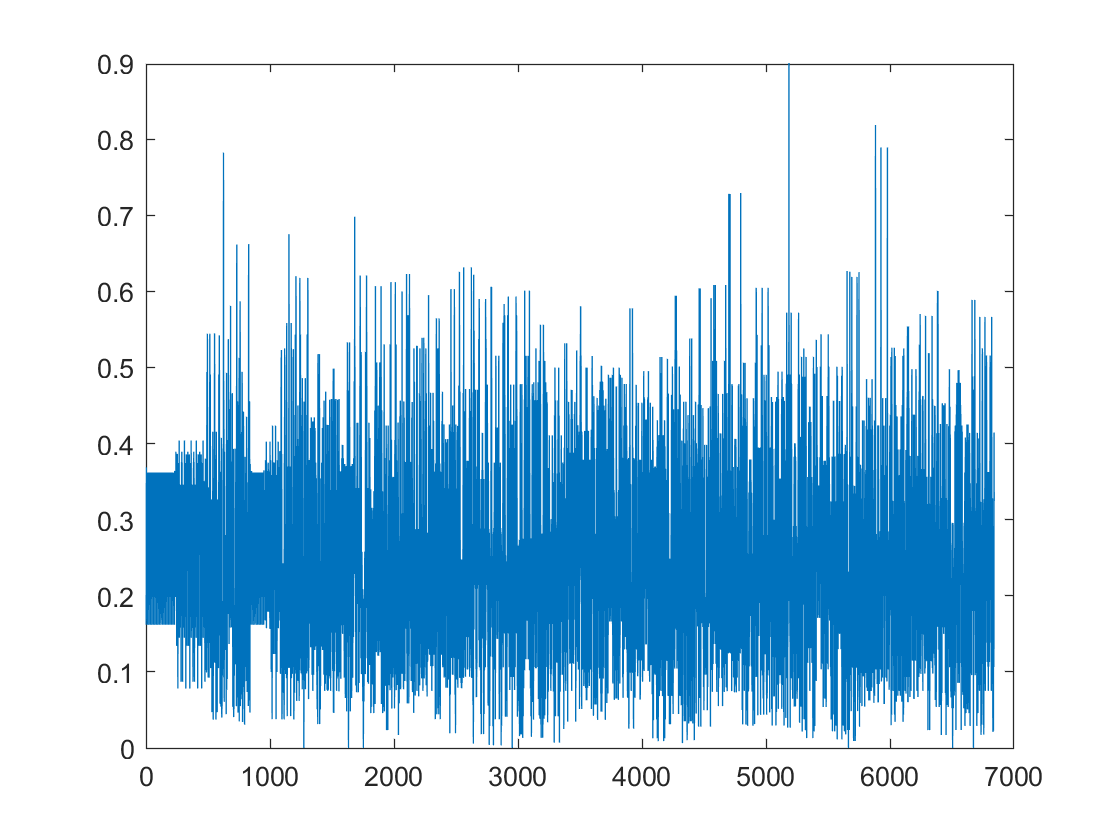

sdrTransmitter.release()
plot(abs(txWaveform_t))

[mpduList, delimCRCFails, ampduStatus] = wlanAMPDUDeaggregate(p1, HTconfig, 'DataFormat', 'octets');

[rxFrameCfg, rxMSDU, status] = wlanMPDUDecode(qos_data.p1, HTconfig,'DataFormat', 'octets');